r_W =    1.000000000000000
   0.998797983079708
   0.996474442955637
   0.991982961313107
   0.983300756279176
   0.966517970589153
   0.934073487331150
   0.871393160918610
   0.749764670006452
   0.520669909726703


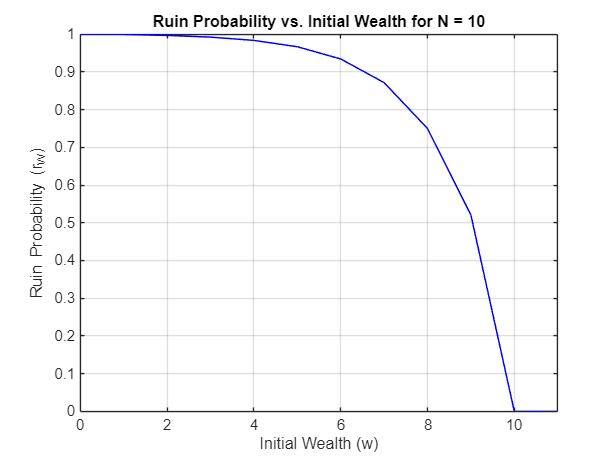

r_W =    1.000000000000000
   0.999999999999996
   0.999999999999987
   0.999999999999971
   0.999999999999941
   0.999999999999881
   0.999999999999766
   0.999999999999543
   0.999999999999113
   0.999999999998282


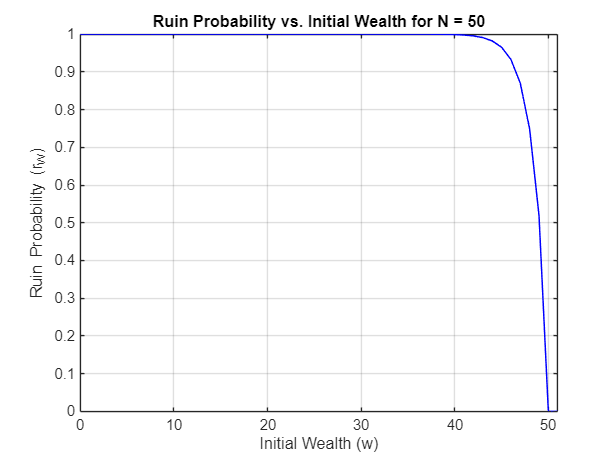

r_W =    1.000000000000000
   1.000000000000000
   1.000000000000000
   1.000000000000000
   1.000000000000000
   1.000000000000000
   1.000000000000000
   0.999999999999999
   0.999999999999999
   0.999999999999999


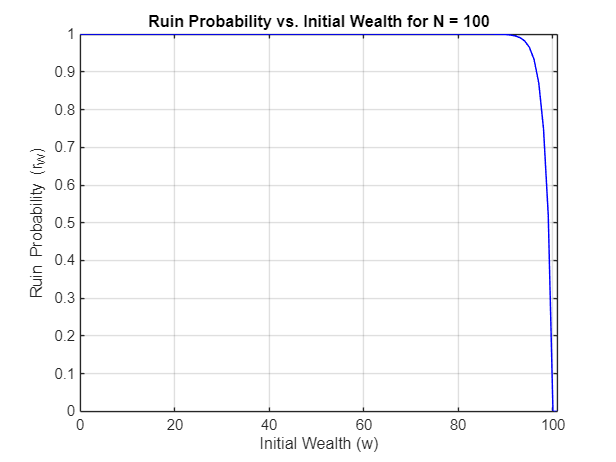

format long

N_values = [10, 50, 100]; 
n = length(N_values);
p_1 = 5/18;
p_2 = 1/36;
q = 25/36;


for i = 1:n
    N = N_values(i);

P = zeros(N+2, N+2);  

P(1,1) = 1;
P(N+1,N+1) = 1;
P(N+2,N+2) = 1; 

for row = 2:N
    P(row, row-1) = q; 
    P(row, row) = 0;
    P(row, row+1) = p_1;
    P(row, row+2) = p_2;
end

P;
Q = P(2:N, 2:N); %transient to transient 
R = [P(2:N, 1), P(2:N, N+1), P(2:N, N+2)]; %transient to absorption
I = eye(size(Q));
F = inv(I-Q);
H = F*R;
H_full = [P(1,1), P(1,N+1), P(1,N+2); H; P(N+1,1), P(N+1,N+1), P(N+1,N+2); P(N+2,1), P(N+2,N+1), P(N+2,N+2)];
r_W = H_full(:,1)
figure;
plot(0:N+1, r_W, 'b', 'LineWidth', 1);
xlabel('Initial Wealth (w)');
ylabel('Ruin Probability (r_W)');
title(['Ruin Probability vs. Initial Wealth for N = ', num2str(N)]);
grid on;

xlim([0 N+1])
ylim([0.000 1.000])

end